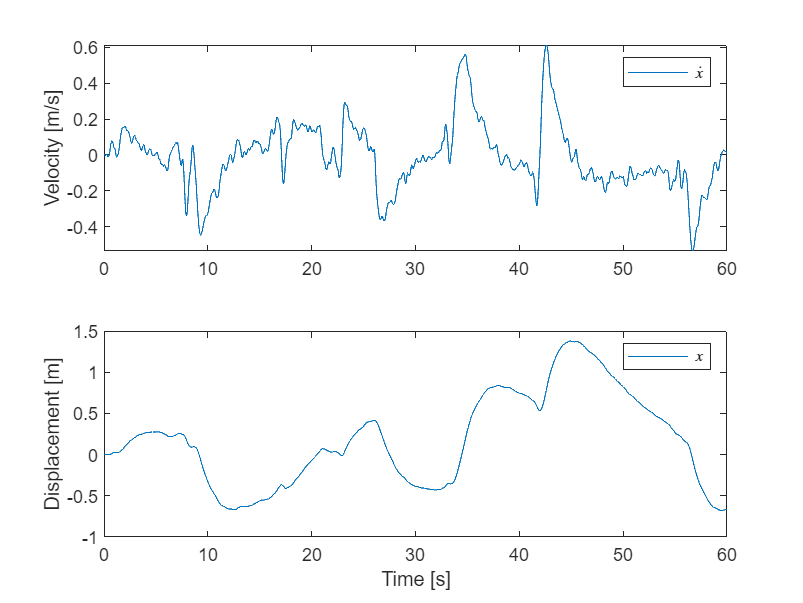

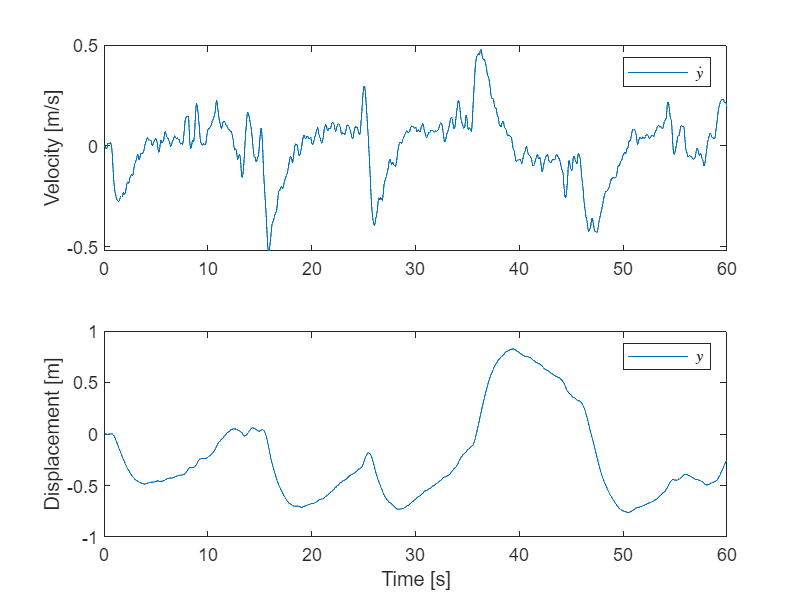

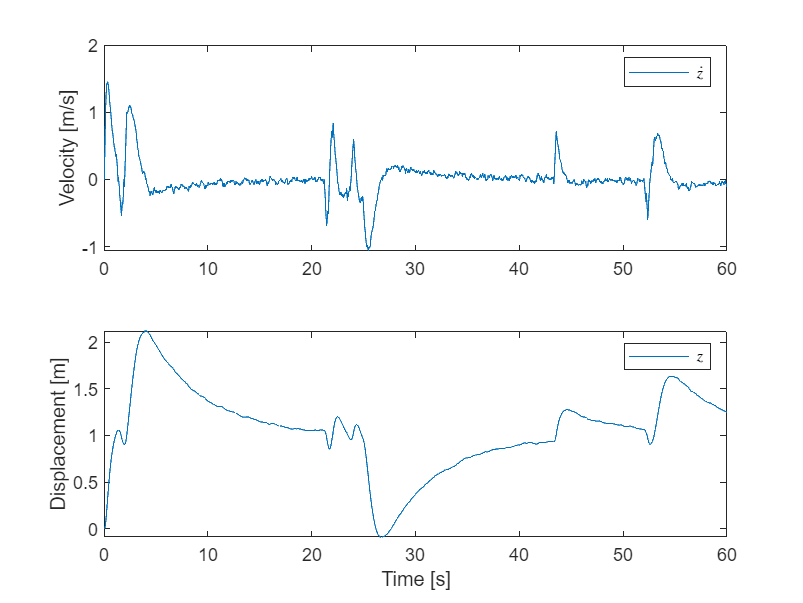

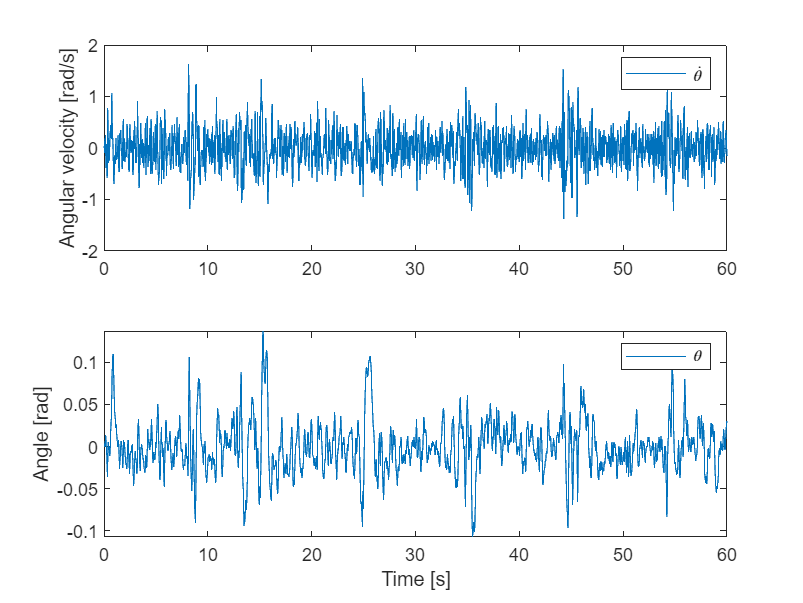

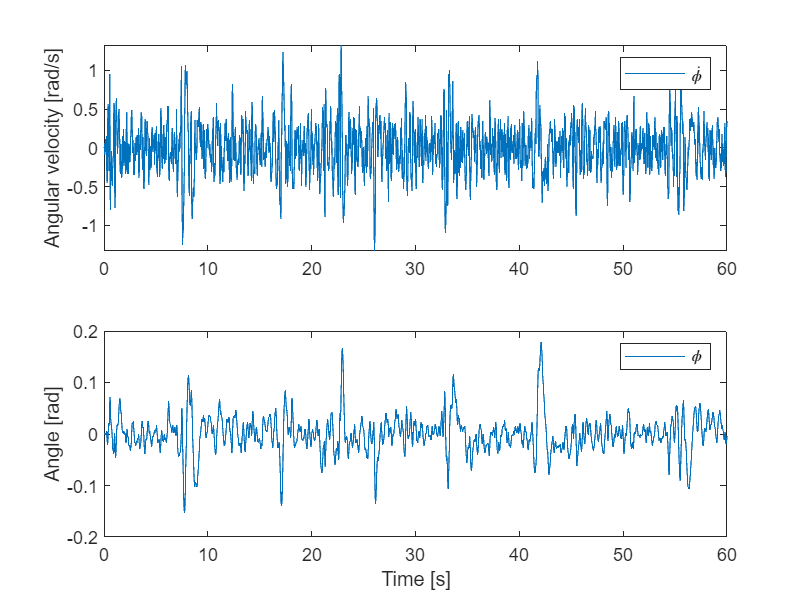

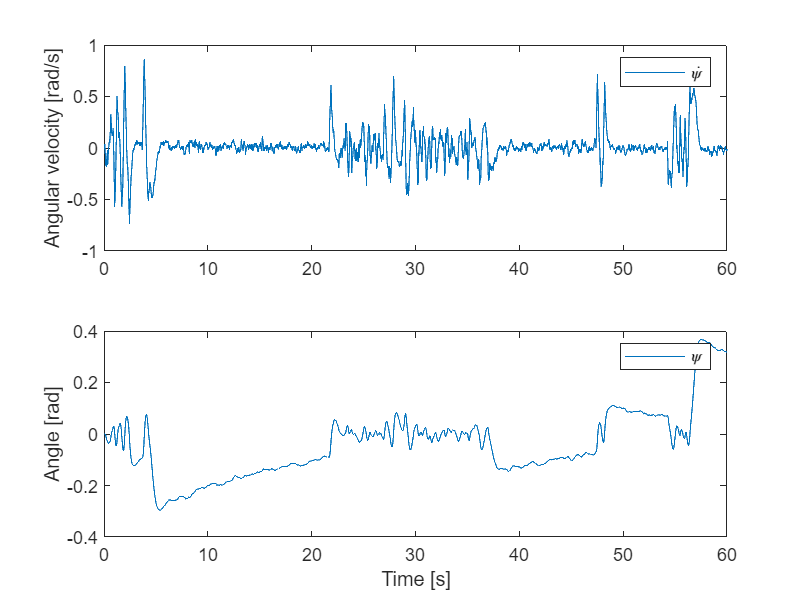

clc
clear

R_translate =@(theta,phi,psi) [cos(phi)*cos(psi), cos(phi)*sin(psi), -sin(phi); cos(psi)*sin(phi)*sin(theta) - cos(theta)*sin(psi), cos(psi)*cos(theta) + sin(phi)*sin(psi)*sin(theta), cos(phi)*sin(theta); sin(psi)*sin(theta) + cos(psi)*cos(theta)*sin(phi), cos(theta)*sin(phi)*sin(psi) - cos(psi)*sin(theta), cos(phi)*cos(theta)];
R =@(ang) R_translate(ang(1),ang(2),ang(3));

g = 9.82;
m = 1.513;
I_xx = 0.0185; 
I_yy = 0.0201;
I_zz = 0.0286;
kt = 0.011;
l_theta = 0.175;
l_phi = 0.175;
km = 327e-6;

n=60*800;

x = zeros(12,n);
u = zeros(4,n);

x_dot = zeros(12,1);
Ts = 1/800;
e = zeros(12,n);
omega_u = zeros(4,n);
omega_u_lin = m*g/(4*kt)*ones(4,1);
omega_u_i = zeros(3,n);

roll_rate =     PID_Class(500,0,0,20,1/400,omega_u_lin(1)*4);
pitch_rate =    PID_Class(500,0,0,20,1/400,omega_u_lin(1)*4);
yaw_rate =      PID_Class(500,0,0,20,1/400,omega_u_lin(1)*4);

roll =          PID_Class(3,0,0.1,10,1/50,0);
pitch =         PID_Class(3,0,0.1,10,1/50,0);
yaw =           PID_Class(3,0.2,0.1,10,1/50,0);

pid_x =         PID_Class(0.4,0.005,0.1,10,1/10,0);
pid_y =         PID_Class(0.4,0.005,0.1,10,1/10,0);
altitude =      PID_Class(2.5,0.4,1,10,1/25,0);

pid_vx =        PID_Class(0.5,0.1,0.08,10,1/25,0.35);
pid_vy =        PID_Class(0.5,0.1,0.08,10,1/25,0.35);
pid_vz =        PID_Class(200,0,0,20,1/50,omega_u_lin(1)*4);

ref = zeros(12,n);
ref(12,:) = 1;
ref(10,:) = 0;
ref(11,:) = 0;

cov_mat = diag([1/1000*ones(3,1);1/1000*ones(3,1);1/1000*ones(3,1);1/1000*ones(3,1)]);
wgn = mvnrnd(zeros(12,1),cov_mat,n).';

prog = waitbar(0, 'Starting');
for i=2:n
    ref(1:9,i) = ref(1:9,i-1);
    omega_u(:,i) = omega_u(:,i-1); % ZOH the latest value
    if(mod(Ts*i,0.1) == 0)
        ref(7,i) = pid_x.Calculate(ref(10,i) - x(7,i-1)+wgn(7,i-1) );
        ref(8,i) = pid_y.Calculate(ref(11,i) - x(8,i-1)+wgn(8,i-1));
    end
    if(mod(Ts*i,0.04) == 0)
        ref(5,i) = pid_vx.Calculate(ref(7,i) - x(1,i-1)+wgn(1,i-1));
        ref(4,i) = -pid_vy.Calculate(ref(8,i) - x(2,i-1)+wgn(2,i-1));
        ref(9,i) = altitude.Calculate(ref(12,i) - x(9,i-1)+wgn(9,i-1));
    end
    if(mod(Ts*i,0.02) == 0)
        ref(1,i) = roll.Calculate(ref(4,i) - x(10,i-1)+wgn(10,i-1)  );
        ref(2,i) = pitch.Calculate(ref(5,i) - x(11,i-1)+wgn(11,i-1) );
        ref(3,i) = yaw.Calculate(ref(6,i) - x(12,i-1)+wgn(12,i-1) );
        omega_u(1,i) = pid_vz.Calculate(ref(9,i) - x(3,i-1)+wgn(3,i-1) );
    end
    if(mod(Ts*i,0.0025))
        omega_u_i(1,i) = roll_rate.Calculate(ref(1,i) - x(4,i-1)+wgn(4,i-1));
        omega_u_i(2,i) = pitch_rate.Calculate(ref(2,i) - x(5,i-1)+wgn(5,i-1));
        omega_u_i(3,i) = yaw_rate.Calculate(ref(3,i) - x(6,i-1)+wgn(6,i-1));
        omega_u(2:4,i)=R(x(10:12,i-1)) * omega_u_i(:,i);
    end
    u(:,i) = MotorMix(omega_u(1,i),omega_u(2,i),omega_u(3,i),omega_u(4,i));

    x(:,i) = NonLinear_Simulation(x(:,i-1),u(:,i) + omega_u_lin,Ts);
    % x(6,i)= 0;

    waitbar(i/n, prog, sprintf('Progress: %d %%', floor(i/n*100)));
end
close(prog)
Simulation_Plot(x,Ts)

save("Data/PID_Steady_State_Noise.mat","x","u")

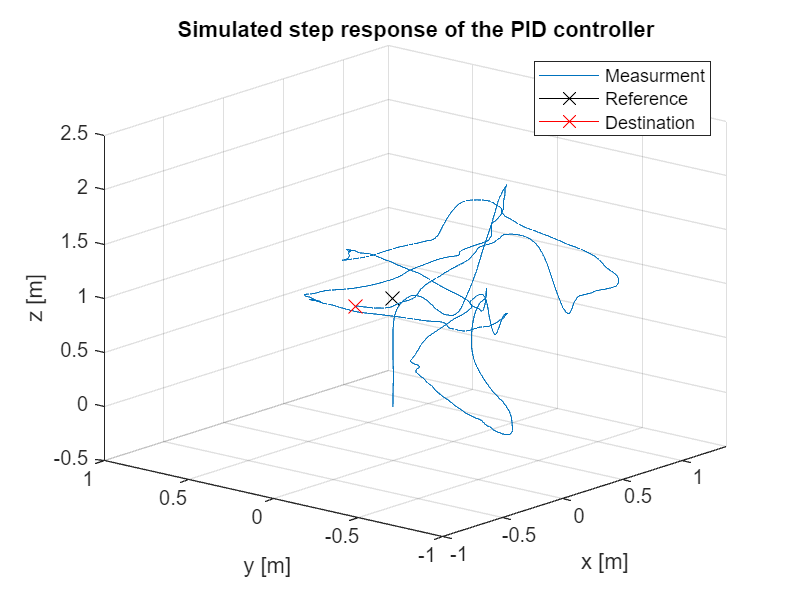

t = linspace(0,size(x,2)*Ts,size(x,2));
figure()
hold on
plot3(x(7,:).',x(8,:).',x(9,:).')
plot3(0,0,1,Marker="x",Color=[0,0,0],MarkerSize=10)
plot3(x(7,end),x(8,end),x(9,end),Marker="x",Color=[1,0,0],MarkerSize=10)
title("Simulated step response of the PID controller")
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")
legend({'Measurment','Reference','Destination'},"Location","northeast")
grid on
hold off
view([-50 20])
saveas(gcf,'Images/Accept_PID_Step','epsc')

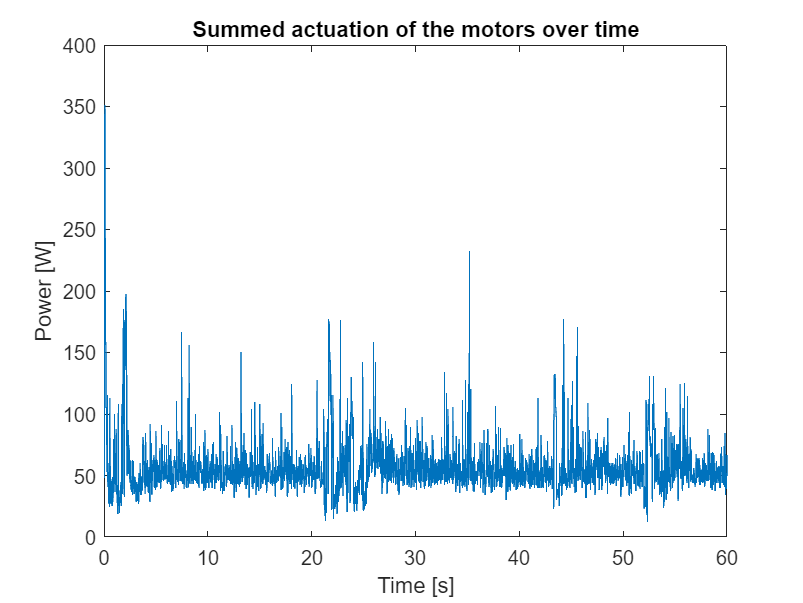


summedActuation = sum(2.3536e-07*(u+omega_u_lin).^3+2.6783e-05*(u+omega_u_lin).^2);
figure()
plot(t,summedActuation)
xlabel("Time [s]")
ylabel("Power [W]")
title("Summed actuation of the motors over time")
saveas(gcf,'Images/Accept_PID_Step_Actuation','epsc')

totalActuation = [Ts * ones(1,n)] * summedActuation.'

totalActuation = 3.3209e+03

## Step response

We calculate the norm of each timestep and the norm of the reference to plot a stepresponse and get stepinfo

trajectory = vecnorm([x(7,:);x(8,:);x(9,:)],2);
reference = norm([ref(10,end),ref(11,end),ref(12,end)],2);
figure()
plot(t,trajectory)
title("Step response of the simulated PID controller")
ylabel("2-norm of the trajectory [m]")
xlabel("Time [s]")
stepinfo(trajectory,t,reference)

ans = struct with fields:
         RiseTime: 0.7200
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.5139
      SettlingMax: 2.1895
        Overshoot: 118.9516
       Undershoot: 0
             Peak: 2.1895
         PeakTime: 4.0488


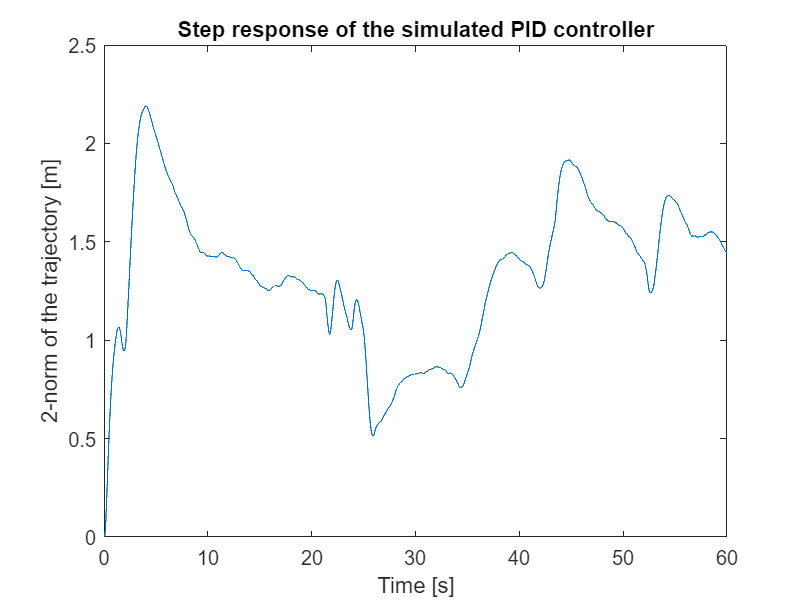

saveas(gcf,'Images/Accept_PID_Step_Plot','epsc')